## Задача 2: Взаимная корреляция временных рядов

## Постановка задачи

Приведены данные по заболеваемости и выздоровлению от COVID-19 в Москве в период 12.03.20-29.11.20 в формате time_series_COVID.xlsx. Вычислить средню продолжительность лечения.

#### Импортирование

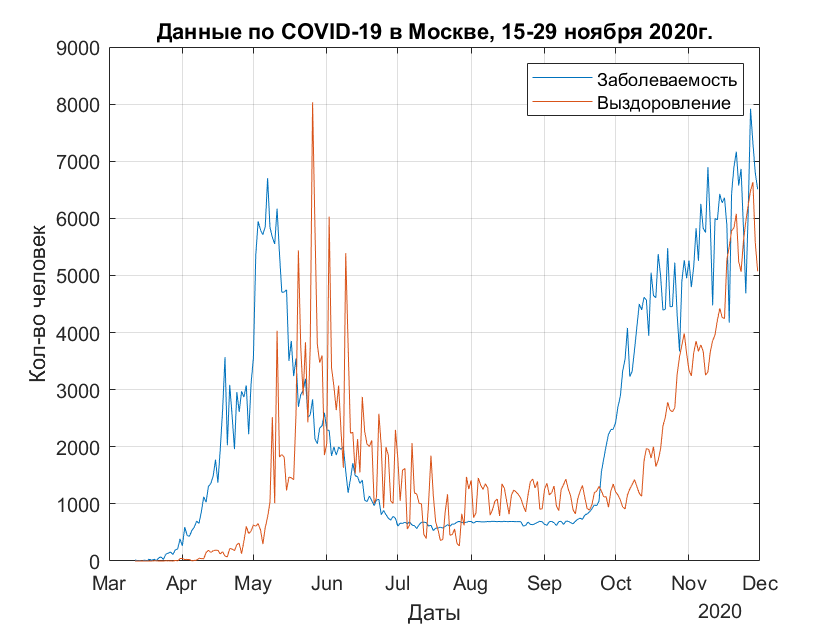

T2 = readtable('time_series_COVID.xlsx','Sheet','Chart data', ...
    'Range','A2:C265', 'ReadVariableNames',false);
dates = T2.Var1; % Даты
infected = T2.Var2; % Заболевшие
recovered = T2.Var3; % Выздоровевшие
plot(dates, infected, dates, recovered)
title('Данные по COVID-19 в Москве, 15-29 ноября 2020г.')
xlabel('Даты')
ylabel('Кол-во человек')
legend('Заболеваемость','Выздоровление', 'Location','northeast')
grid on

#### Рассчет взаимной корреляции

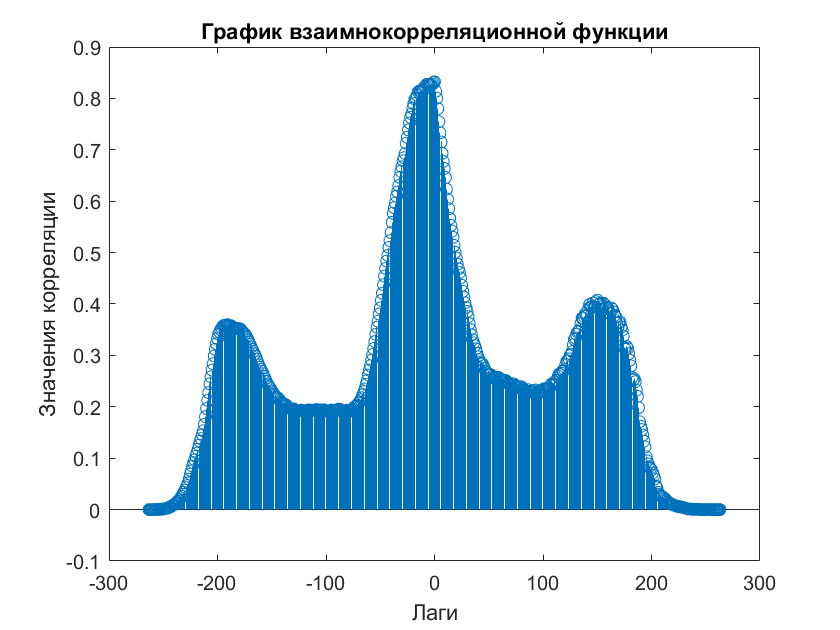

[conn, lags] = xcorr(infected, recovered, 'normalized');
stem(lags,conn)
title('График взаимнокорреляционной функции')
xlabel('Лаги')
ylabel('Значения корреляции')

[recovtime, I] = max(rho);
disp(I)

    18



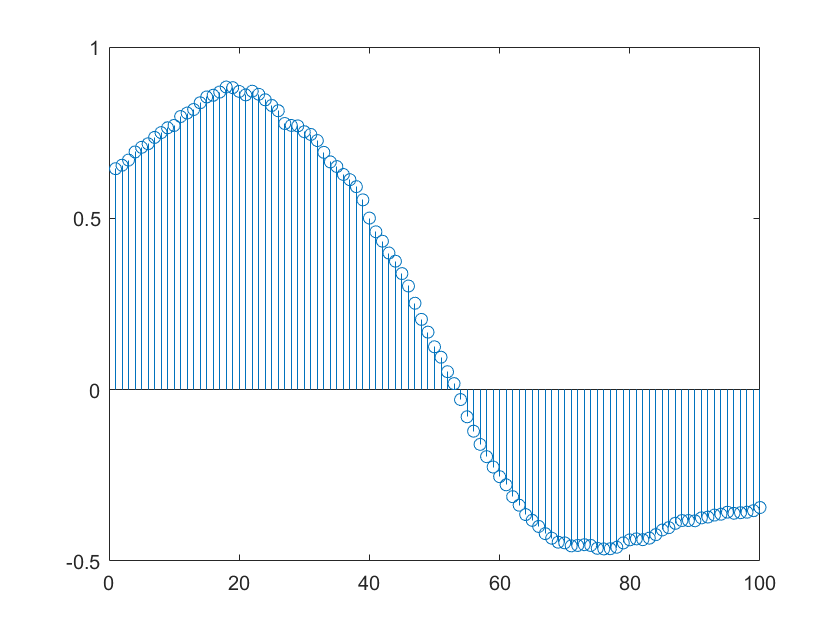

rho2 = zeros(100,1);
for k = 1:100
   rho2(k) = corr(infected(1:end-k),recovered(k+1:end));
end
stem(1:100,rho2)

[recovtime2, I2] = max(rho2);
disp(I2)

    18

